clc
clear all
%% 3d hermite curve

%points
P=[0 0 0 ; 
   1 1 0 ;
   2 9 0 ;
   3 0 0 ]

P =      0     0     0
     1     1     0
     2     9     0
     3     0     0


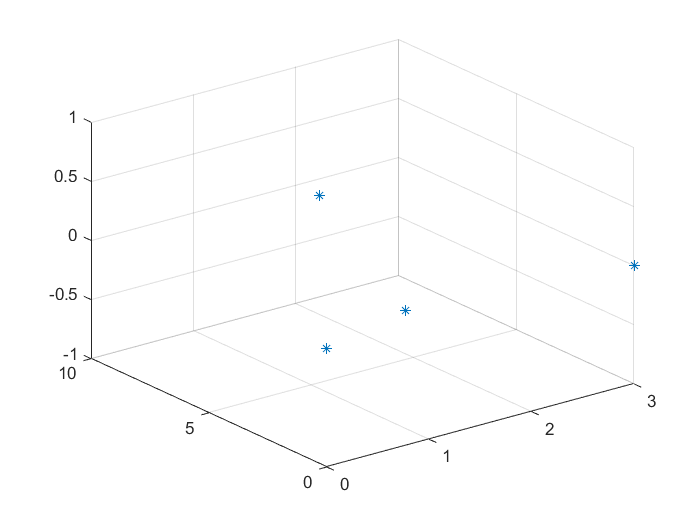

plot3(P(:,1),P(:,2),P(:,3),'*');
grid on
hold on

u1=0;
u2=1/3;
u3=2/3;
u4=1;


M=[2 -2 1 1;
  -3 3 -2 -1;
   0 0 1 0;
   1 0 0 0]

M =      2    -2     1     1
    -3     3    -2    -1
     0     0     1     0
     1     0     0     0


U=[u1.^3 u1.^2 u1 1;
    u2.^3 u2.^2 u2 1;
    u3.^3 u3.^2 u3 1;
    u4.^3 u4.^2 u4 1]

U =          0         0         0    1.0000
    0.0370    0.1111    0.3333    1.0000
    0.2963    0.4444    0.6667    1.0000
    1.0000    1.0000    1.0000    1.0000


k=inv(M)*inv(U)

k =     1.0000         0         0         0
    0.0000   -0.0000   -0.0000    1.0000
   -5.5000    9.0000   -4.5000    1.0000
   -1.0000    4.5000   -9.0000    5.5000


N=M*k

N =    -4.5000   13.5000  -13.5000    4.5000
    9.0000  -22.5000   18.0000   -4.5000
   -5.5000    9.0000   -4.5000    1.0000
    1.0000         0         0         0


A=N*P

A =     0.0000 -108.0000         0
   -0.0000  139.5000         0
    3.0000  -31.5000         0
         0         0         0


B=(inv(M))*A

B =          0         0         0
    3.0000   -0.0000         0
    3.0000  -31.5000         0
    3.0000  -76.5000         0


u=0:0.01:1;
u=u'

u =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


u=u.^[3,2,1,0]

u =          0         0         0    1.0000
    0.0000    0.0001    0.0100    1.0000
    0.0000    0.0004    0.0200    1.0000
    0.0000    0.0009    0.0300    1.0000
    0.0001    0.0016    0.0400    1.0000
    0.0001    0.0025    0.0500    1.0000
    0.0002    0.0036    0.0600    1.0000
    0.0003    0.0049    0.0700    1.0000
    0.0005    0.0064    0.0800    1.0000
    0.0007    0.0081    0.0900    1.0000


pu=u*A

pu =          0         0         0
    0.0300   -0.3012         0
    0.0600   -0.5751         0
    0.0900   -0.8224         0
    0.1200   -1.0437         0
    0.1500   -1.2397         0
    0.1800   -1.4111         0
    0.2100   -1.5585         0
    0.2400   -1.6825         0
    0.2700   -1.7838         0


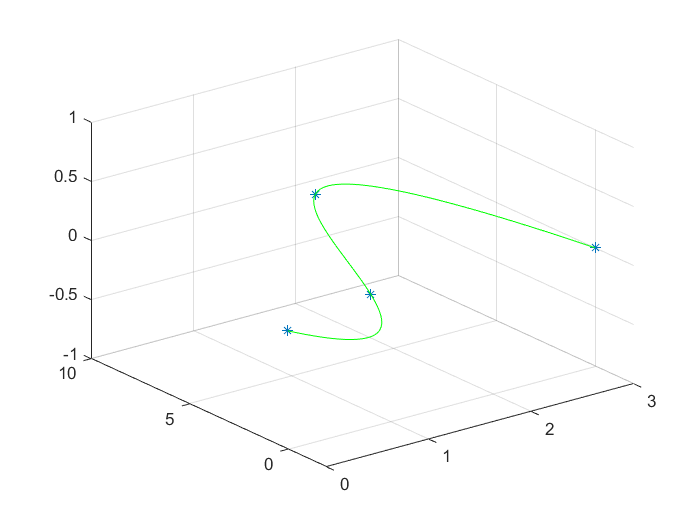

plot3(pu(:,1),pu(:,2),pu(:,3),"Color","g");